I recently found some old notes (from my Master's time), that had really helped me back then to get started with **Matlab **and the **Psychtoolbox (PTB)**, so I thought to share them.

I will create 5 to 6 notebooks (or matlab live scripts) that will include notes about:

- Some basic matlab introductory information

- Introduction on PTB, Screens and Windows

- Introduction on timing 

- Images in PTB

- Animation in PTB

This is the 1st of the 5 notebooks. I will first provide a few matlab notes that I think are important before diving into the powerfull **psychtoolbox.**

Please note that I will be updating them at times.

% -------------------------------------------------------------------------------------------------- %

## NOTEBOOK 1

#### MATLAB AND PSYCHOPHYSICS TOOLBOX (PTB) PART 1:

#### SOME BASIC MATLAB COMMANDS AND OPERATIONS:

### **Basic Operations**

**Variables in Matlab**. A variable is sort of like a box. It has a certain shape and a certain dimension with a label naming it. In this box you can put the (virtual) item(s) you need ( e.g. a number, a name, an image). And variables come of ifferent types:

a. Scalar:

a = 1

a = 1

b. Row vector:

a = [1 2 3 4 5 6]

a =      1     2     3     4     5     6


or

a = [1, 2, 3, 4, 5, 6]

a =      1     2     3     4     5     6


c. Column vector:

b = [1; 2; 3; 4; 5; 6]

b =      1
     2
     3
     4
     5
     6


But there is an easier way to get a column vector (especially when we want to do something like the above):

b = a'

b =      1
     2
     3
     4
     5
     6


Using the symbol: **'**, we can easily transpose a  vector or a matrix in matlab.

d. Matrix:

a = [1 2 3 4; 5 6 7 8; 9 10 11 12]

a =      1     2     3     4
     5     6     7     8
     9    10    11    12


**NOTE: **Scalars and vectors are just special cases of matricies. 

% ---------------------------------

**The size function.** With the size function we can determine the size of a variable.

size(a)

ans =      3     4


For more information about this function (and about any other function that I will mention), type 'help' and the function name on the command window:

help size

 size   Size of array.  
    D = size(X), for M-by-N matrix X, returns the two-element row vector
    D = [M,N] containing the number of rows and columns in the matrix.
    For N-D arrays, size(X) returns a 1-by-N vector of dimension lengths.
    Trailing singleton dimensions are ignored.
 
    [M,N] = size(X) for matrix X, returns the number of rows and columns in
    X as separate output variables. 
    
    [M1,M2,M3,...,MN] = size(X) for N>1 returns the sizes of the first N 
    dimensions of the array X.  If the number of output arguments N does
    not equal NDIMS(X), then for:
 
    N > NDIMS(X), size returns ones in the "extra" variables, i.e., outputs
                  NDIMS(X)+1 through N.
    N < NDIMS(X), MN contains the product of the sizes of dimensions N
                  through NDIMS(X).
 
    M = size(X,DIM) returns the lengths of the specified dimens

Try this:

[nrows, ncols] = size(a)

nrows = 3

ncols = 4

It will output the number of rows (nrows) and the number of columns (ncols).

Back to variables. Variables can also have three or more dimensions. We saw that a scalar is a 1x1 matrix. Other functions that are size related are: `ndims` and `length` functions. 

Initialize a variable using the `ones `or `zeros `function and ask for its length and ndims:

a = zeros(3,4)

a =      0     0     0     0
     0     0     0     0
     0     0     0     0


length(a)

ans = 4

ndims(a)

ans = 2

**Special characters and operations.** for more info type:

help ops 

  Operators and special characters.
 
  Arithmetic operators.
    plus       - Plus                               +    
    uplus      - Unary plus                         +    
    minus      - Minus                              -    
    uminus     - Unary minus                        -    
    mtimes     - Matrix multiply                    *    
    times      - Array multiply                    .*    
    mpower     - Matrix power                       ^    
    power      - Array power                       .^    
    mldivide   - Backslash or left matrix divide    \    
    mrdivide   - Slash or right matrix divide       /    
    

When programming it is strongly recommended to use comments. In case you don't know this yet, in matlab we add comments using the percent (%)  sign:

% this is a comment

Comments are extremely useful for us and for others. Try writing a block of code without comments, and don't look at it for a few months. I bet you that a few months later, when you see your own code, you will probably be thinking "what was I trying to do here?"

Now let's try some addition.

% create 2 variable/matricies and add them in a third 
% variable/matrix
a = [1 2]

a =      1     2


b = [3 4]

b =      3     4


c = a + b

c =      4     6


As you can see we added the rows with the rows and the columns with the columns. The same logic appllies for subtraction but not for multiplication or division (I will probably make a seperate notebook on matrix operartions). For now, keep in mind that when adding 2 matricies, we add the rows with the rows and the columns with the columns. 

***Also, keep in mind that it's good to use semicolon (;) at the end of your commands. For example***:

c = a + b; 

This prevents matlab from printing the output. Even though now, it may not seem necessary, it can be really annoying in the future when running long scripts with for and while loops, etc.. besides (especially when working in loops), not using semicolons results in your code running slowly. 

**The colon (:). **This is used as "to" or "step":

b = 1:5 % create a 1 to 5 vector

b =      1     2     3     4     5


c = 1:.5:4 % create a 1 to 4 vector and increment by 0.5 each time

c =     1.0000    1.5000    2.0000    2.5000    3.0000    3.5000    4.0000


**Indexing (subscripts). **We use parentheses to indicate subscripts. Subscritps need to be positive integers, in matricies of any size:

b(2) % which is the 2nd elemt of b?

ans = 2

b(1:3) % which are the first 3 elements of b?

ans =      1     2     3


The second command `b(1:3) `is the same as:

b([1 2 3])

ans =      1     2     3


Variable/matrix b is of size 1x5. Lets try indexing with matricies of different size:

a = [1 3 5 6; 4 6 3 2; 5 8 9 5] % this is a 3x4 matrix

a =      1     3     5     6
     4     6     3     2
     5     8     9     5


Exactract the entire 2nd row:

a(2,:) % the colon is used as: everything 

ans =      4     6     3     2


% (so, 2nd row and all columns)

Now, extract the element in row 3, column 4:

a(3,4) % the output is 5

ans = 5

try this:

a([1 3], :) % we explicitely ask for rows 1 and 3 and all columns

ans =      1     3     5     6
     5     8     9     5


a([1 2], [2 4]) % extract rows 1 and 2 and columns 2 and 4

ans =      3     6
     6     2


what if we want to change the value of a specific element/item in a matrix? Let's say we want to change the value of the item in row 3, column 3 (the value now is 9) to 0:

a(3,3)= 0 % now 9 has changed to 0

a =      1     3     5     6
     4     6     3     2
     5     8     0     5


**Some basic math stuff.** For more info type:

help arith


arith not found.

Use the Help browser search field to search the documentation, or
type "help help" for help command options, such as help for methods.



The operations are: `+ - * / ^ .* ./ .^`

Scalar math. Simple operations of scalars:

2*3 

ans = 6

or...

a = 2

a = 2

b = 3

b = 3

c = a*b

c = 6

The above two codes are exactly the same.

Now try some more operations:

4 ^ 1.5

ans = 8

2 * 3 + 2

ans = 8

2 * (3 + 1)

ans = 8

NOTE: you can try the above operations in variables:

a = 4

a = 4

b = 1.5

b = 1.5000

c = a ^ b

c = 8

.. and so on.

**Basic Vector and Scalar math. **

Create a 1x3 vector:

a = [2 4 6]

a =      2     4     6


b = 2*a

b =      4     8    12


**b** multiplies every element of vector **a** by 2. Thus` b = [4 8 12]`

c = a + 5 

c =      7     9    11


**c** adds 5 to every element of vector **a**

Let's try something else:

d = a^2 % this will raise an error.

d =      4    16    36


This will print an error because **a **is not square and we want to do element-wise operation. So:

d = a.^2 % will perform the element-wise power operation

b =      1     3     5


**Let's try to multiply vectors:**

b = [1 3 5]

a2 =      2
     4
     6


% c = a * b

c =      2     6    10
     4    12    20
     6    18    30


Again, we will get an error. This is because in matrix multiplication and linear algebra the number of columns in the 1st matrix need to match the number of rows in the 2nd matrix, thus we can try:

a2 = a' % transpose a 

c =      2    12    30


c = a2 * b

but what if we want to just do element-wise multiplication of **a **and **b**?

c = a.*b 

x =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


this will multiply every elemnt of a with the corresponding elements of b, so:

`c = [2 12 30]`

**Built-in functions**

There are **a lot of** built-in functions in matlab. Some are: ***sin, cos, tan, acos, atan, exp, log, log10, sqrt***.....

try these:

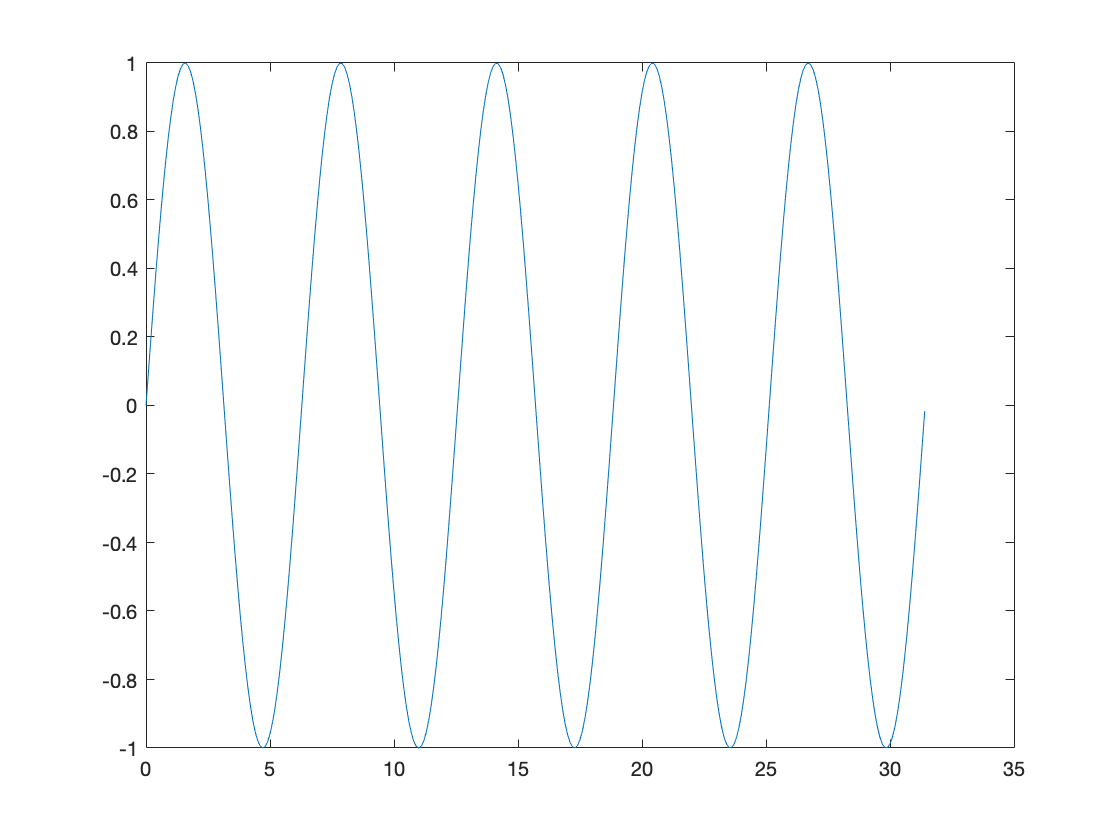

x = 0:.1:10*pi

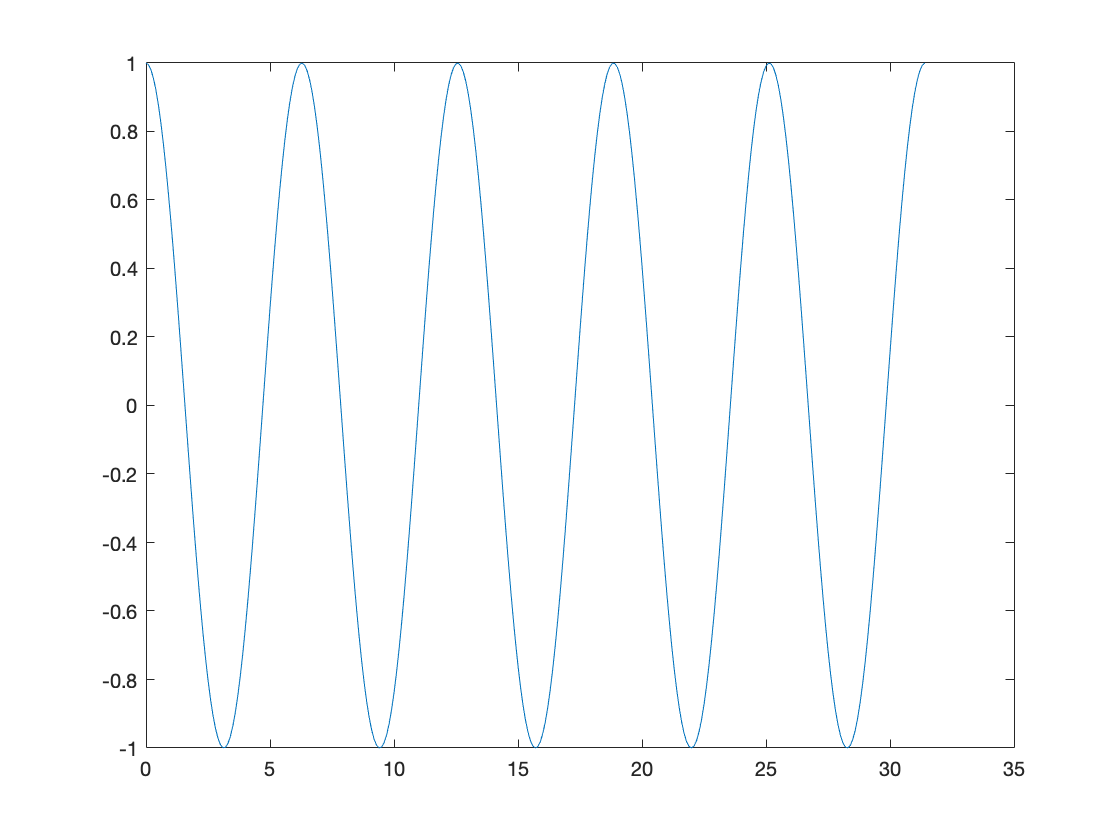

plot(x, sin(x)) % plot the above

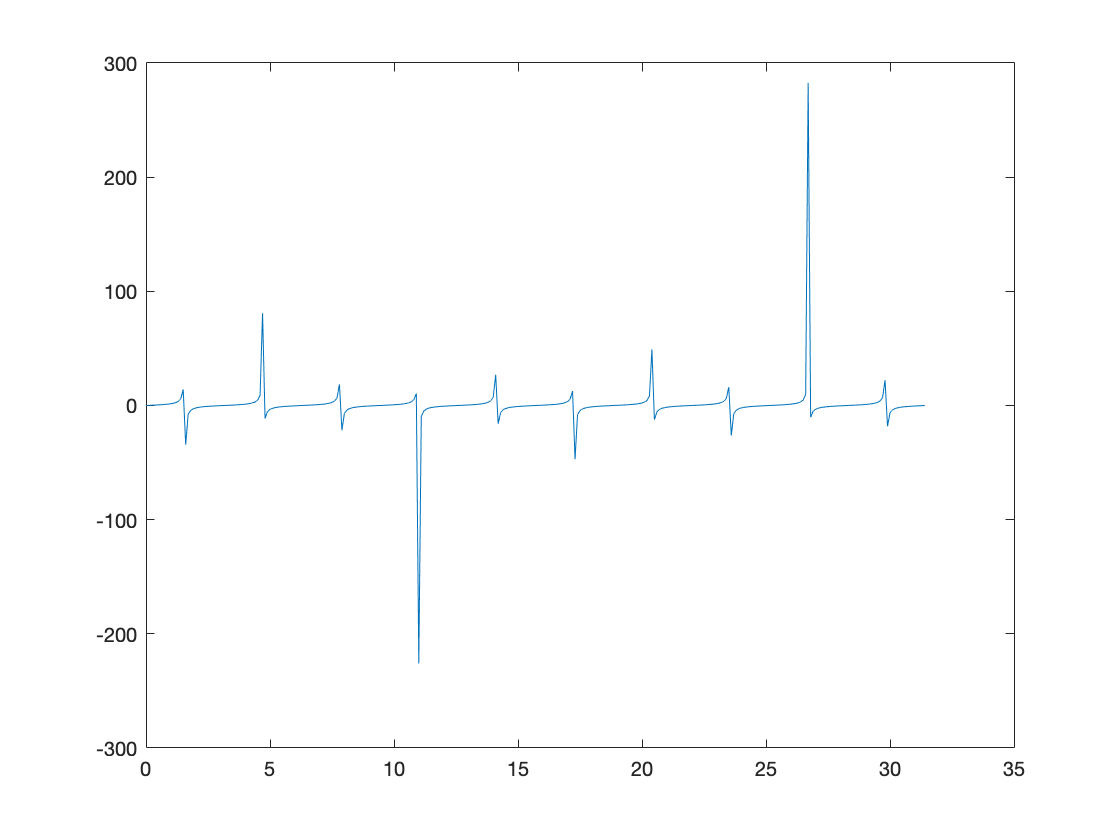

plot(x, cos(x))

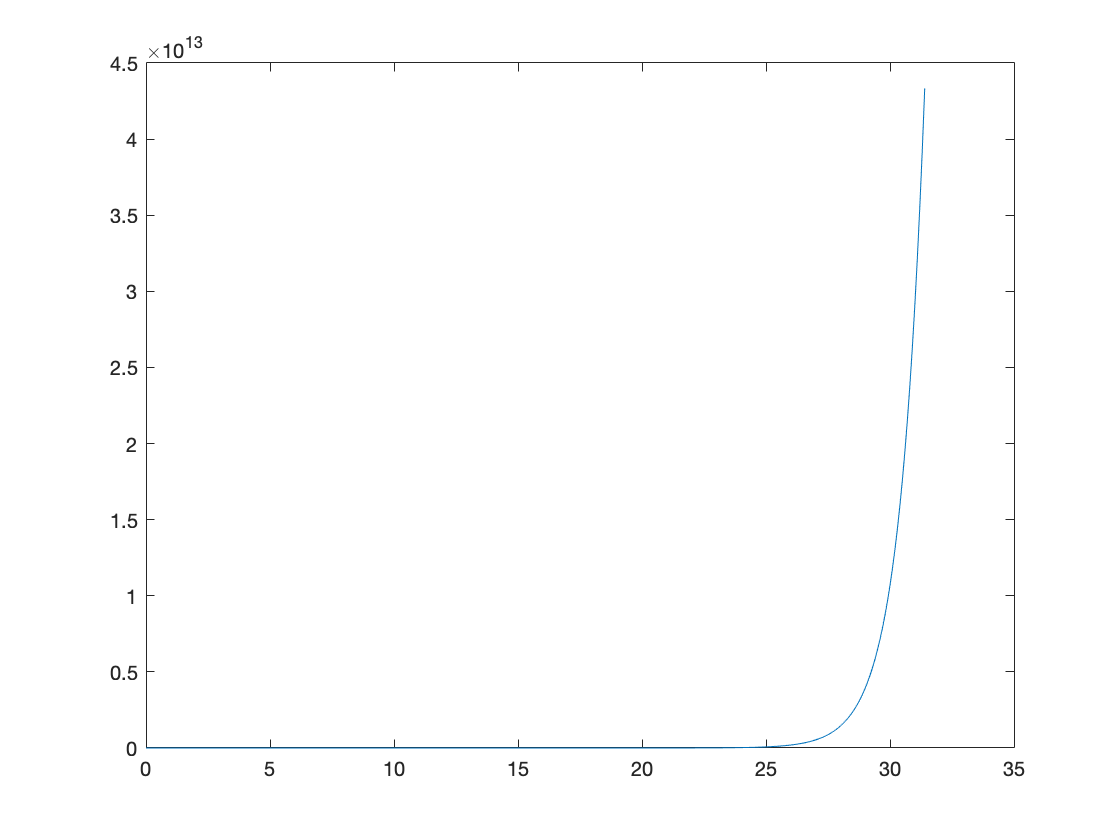

plot(x, tan(x))

plot(x, exp(x))

It is very easy to use them. 

Let's see the built-in functions:*** round, fix, ceil, rem, sign***

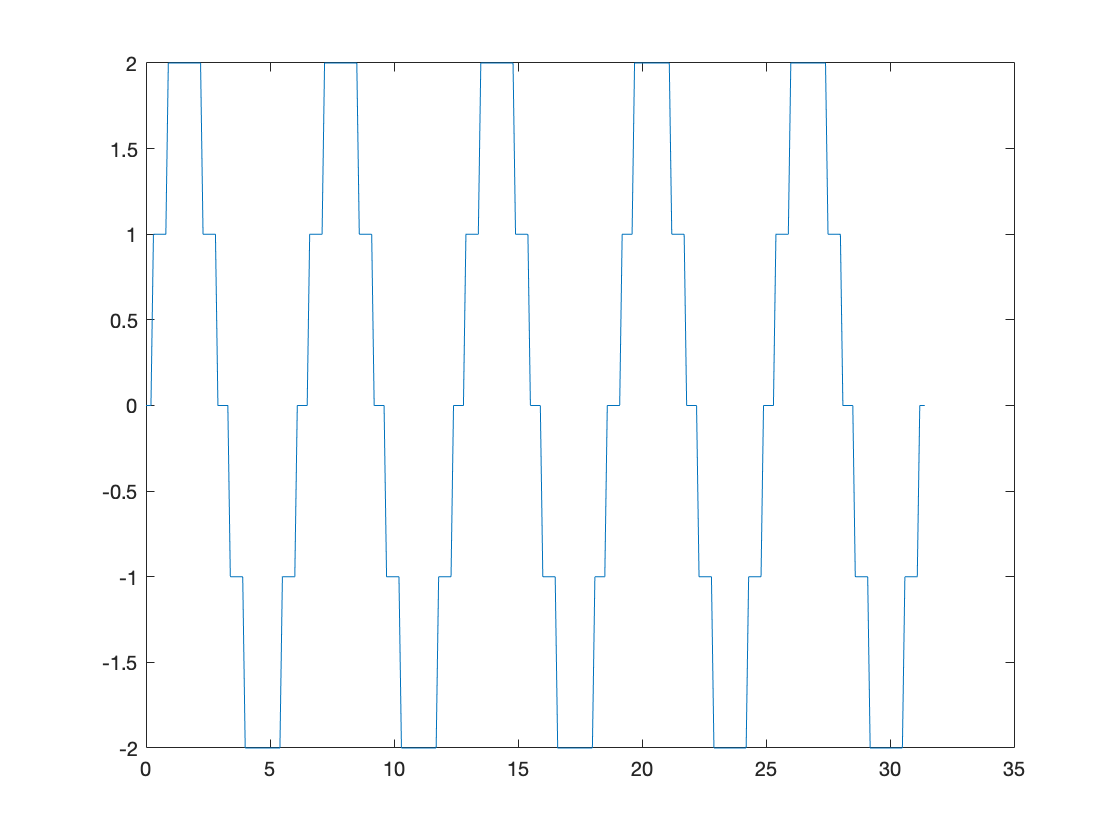

plot(x, round(2*sin(x)))

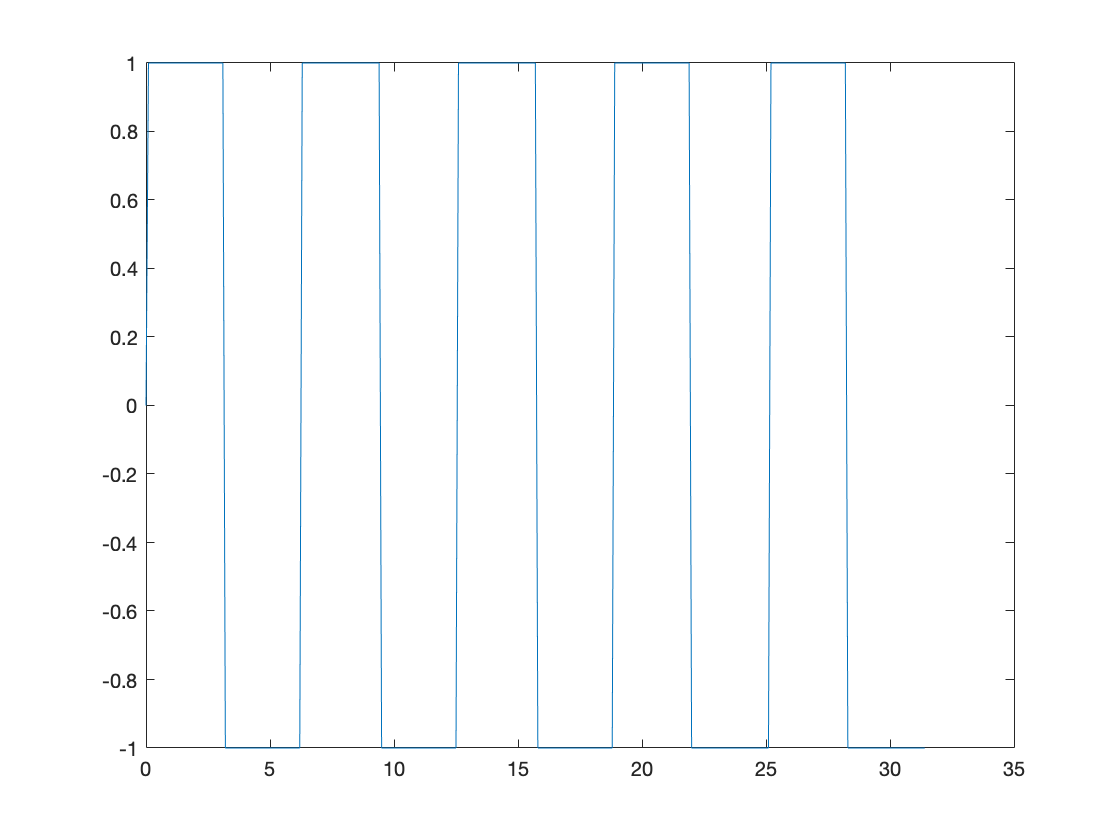

plot(x, sign(2*sin(x)))

If we want to get random integerers from 1 to n, we can use*** floor:***

floor(8*rand(1,10)) + 1 % get 10 random integers from 1 to 8

ans =      1     3     5     8     8     2     8     8     4     7


we can also **shuffle** the arrangement of an array using **randperm**:

a = 1:2:22

a =      1     3     5     7     9    11    13    15    17    19    21


b = randperm(11) % because we have 11 elements in a

b =      7     1     2     6    10    11     4     8     3     9     5


c = a(b)

c =     13     1     3    11    19    21     7    15     5    17     9


now **a **has the shuffled arrangement of **b**. We could also right it as:

c = a(randperm(length(a))) % also shuffles the arrangement of a 

c =     11    15    17     7    13     3     5    21     9     1    19


**Complex numbers. **

In matlab, complex numbers can be enterted like this:

a = 1+1i

a = 1.0000 + 1.0000i

which is tha same as:

a = 1+sqrt(-1)

a = 1.0000 + 1.0000i

The variables **i **and **j **are automatically set up to equal` sqrt(-1)`. But given that these variables are often used as indicies in **for** loops, it's better to use `1i `instead.

We can also use the **complex** built-in function:

a = complex(1, -4)

a = 1.0000 - 4.0000i

There are several functions for complex numbers in matlab:*** angle, abs, conj, real, imag***. 

**NOTE:** be careful with transpose. **a' **is in fact the complex conjugate transpose (the same as a normal transpose for real numbers). 

Take a look at this example:

a = 1i*[1; 2; 3]

a =    0.0000 + 1.0000i
   0.0000 + 2.0000i
   0.0000 + 3.0000i


a'

ans =    0.0000 - 1.0000i   0.0000 - 2.0000i   0.0000 - 3.0000i


a.'

ans =    0.0000 + 1.0000i   0.0000 + 2.0000i   0.0000 + 3.0000i


### **Data Handling**

There are several types of variables (logical values, strings, nans, structures, cells, etc..). Earlier we saw how to store and how to do some basic operations on numbers, however there are times that we need to deal with other types of data, such as: logical values, strings, and so on. 

**Logical operators.**  Most of matlab variables are numeric. But, there is the spacial logical type, which can have one of two values: `true (non-zero) `and `false (zero). `Usually the digit 1 is used to indicate a true value, however, matlab treats any non-zero value as true. There are several ways to create a logical variable:

b = [true false false true true false]

b = 1×6 logical array
   1   0   0   1   1   0


this is the same as:

b = logical([1 0 0 1 1 0])

b = 1×6 logical array
   1   0   0   1   1   0


In fact, true and false are functions, simillar to the functions ones and zeros:

true(2,4)

ans = 2×4 logical array
   1   1   1   1
   1   1   1   1


this can be also written as:

ones(2,4)

ans =      1     1     1     1
     1     1     1     1


we can use the logical variables  as  a mask to perform **logical indexing**:

d = 5:-1:1

d =      5     4     3     2     1


d(b)

ans =      5     2     1


In this case, the logical variable that acts as a mask must be of the same size as the variable it is indexing. The values indexed as` true a`re returned. This is useful when using logical expressions. 

**Logical expressions. **

Relational operators. For more information type:

help relop


relop not found.

Use the Help browser search field to search the documentation, or
type "help help" for help command options, such as help for methods.



The logical expressions are:` < <=  > >= == ~=.` Logical expressions are often used in if statements. When using an expression like `a <= b`, b must be the same size as a.

a = 1:5

a =      1     2     3     4     5


a > 3

ans = 1×5 logical array
   0   0   0   1   1


b = ones(1,5)*2

b =      2     2     2     2     2


a > b

ans = 1×5 logical array
   0   0   1   1   1


Logical operators 

Negation **~ **

a = [1 0 1]

a =      1     0     1


~a

ans = 1×3 logical array
   0   1   0


Logical comparisons 

**& | xor**

a = [1 0 1]

a =      1     0     1


b = [0 0 1]

b =      0     0     1


a&b

ans = 1×3 logical array
   0   0   1


a|b

ans = 1×3 logical array
   1   0   1


There are cases that we want to do **multiple comparisons **at once. In matlab of course this is possible but we need to follow a few rules. Take a look at this example:

a = 3

a = 3

a1 = 0 < a < 2

a1 = logical
   1


If you run this, you will notice that the answer is true, which is not the case. It is true for the 1st part `(0<a),`  but not for the 2nd part `(a<2).` This is because matlab makes the comparisons in succession. It compares a against 0 and because 3 is greater than 0 it returns `true`. Then it compares the answer (result) against 2. The result here is 1 and 1 < 2, thus it returns true again. Thus, we need to be careful with the syntax:

(0<a) & (a<2)

ans = logical
   0


Now, it is correctly 0

Some useful logical functions are: ***any, all, find. ***

The value returned by` any(a)` is true if any of the elements of a are true, and false otherwise. `all(a)` is true only if all the elements of a are true. `Find` returns the indicies of the true elements of a:

a = [1 0 1 0 0 1]

a = 1×6
     1     0     1     0     0     1


find(a) % this should return the indicies 1,3 and 6.

ans = 1×3
     1     3     6


This is very useful in expressions such as:

a = 1:10

a = 1×10
     1     2     3     4     5     6     7     8     9    10


b = find(a>5)

b = 1×5
     6     7     8     9    10


a(b(1:3))

ans = 1×3
     6     7     8


**String characters**

a = 'hello'

a = 'hello'

size(a)

ans = 1×2
     1     5



a2 = 'hello there'

a2 = 'hello there'

size(a2)

ans = 1×2
     1    11



a3 = ['hello'; 'there']

a3 = 2×5 char array
    'hello'
    'there'


size(a3)

ans = 1×2
     2     5


Do you see the difference?

**a** has one row and 5 columns, **a2** has one row and 11 columns (including the space between the words), and **a3** is an array of 2 rows and 5 columns.

Let's try somethings else:

% a4 = ['hello'; 'there'; 'you'] % try to run this

we get an error because the number of columns are inconsistent. So we can try:

a4 = ['hello'; 'there'; 'you  '] % add two spaces after 'you'

a4 = 3×5 char array
    'hello'
    'there'
    'you  '


or try:

a4 = strvcat('hello', 'there', 'you') % will do the same

a4 = 3×5 char array
    'hello'
    'there'
    'you  '


try it with a cell array:

b = {'hello', 'there', 'you'}

b = 1×3 cell array
    {'hello'}    {'there'}    {'you'}


Now try to extract the 2nd element of the cell:

b{2} % to extract elemnts from cells, we use brace brackets 

ans = 'there'

or try to extract a specific letter:

b{2}(4) % from the 2nd word in the cell, extract the 4th letter

ans = 'r'

**The functions disp, sprintf, fprintf. **sprintf and fprint use the same formatted output conventions as in the C programming language. For more info, see help.

a = sprintf('Hello %s. I like photography. I have %d cameras.', 'guys', 2)

a = 'Hello guys. I like photography. I have 2 cameras.'

**NaN values**. Nan means not a number. This variable type is used for missing data. Let's see an example. Let's say we want to calculate the mean of a vector:

a = [3 nan 5 7 nan 2 4 nan]

a = 1×8
     3   NaN     5     7   NaN     2     4   NaN


mean(a)

ans = NaN

The result when w try to calculate the mean of a vector with missing values is nan. There are two ways to handle this. The first way is by removing the nans from the vector and calculating the mean again:

a1 = a(~(isnan(a))) % store the non-nan values in a new variable

a1 = 1×5
     3     5     7     2     4


mean(a1) % compute mean

ans = 4.2000

The second way (which is also very handy) is to use the **nanmean** function of matlab, which automatically handles nan values

nanmean(a)

ans = 4.2000

There are a lot of** "is" **identifying functions that return logical values in matlab: ***isempty, isnan, isfinite, isnumeric, islogical, iseal***.

**Structures. **Variables that are of different types at the sametime are called structures. In other words, think of a structure as a container for storing diffrent types of variables; some can be numeric, some strings, and so on.

struct.name = 'Nancy'

struct = struct with fields:
    name: 'Nancy'


struct.surname = 'Cowan'

struct = struct with fields:
       name: 'Nancy'
    surname: 'Cowan'


struct.subjnumber = 1

struct = struct with fields:
          name: 'Nancy'
       surname: 'Cowan'
    subjnumber: 1


struct.testdone = [1,2,3,6,12]

struct = struct with fields:
          name: 'Nancy'
       surname: 'Cowan'
    subjnumber: 1
      testdone: [1 2 3 6 12]


struct.response = [0.877, 1.435, 0.676, 0.998, 1.221]

struct = struct with fields:
          name: 'Nancy'
       surname: 'Cowan'
    subjnumber: 1
      testdone: [1 2 3 6 12]
      response: [0.8770 1.4350 0.6760 0.9980 1.2210]


struct.correctresp = logical([1,1,0,1,1])

struct = struct with fields:
           name: 'Nancy'
        surname: 'Cowan'
     subjnumber: 1
       testdone: [1 2 3 6 12]
       response: [0.8770 1.4350 0.6760 0.9980 1.2210]
    correctresp: [1 1 0 1 1]


This is how we assign values to the different variables (fields) in the structure. The name of the structure comes before the dot `(.)`, here we call it struct. After the dot we have the different fields, and we can store **any kind** of data in them. So in this structure, the name of the structure is:

- Struct

The names of the **fields** are:

- name

- surname

- subjectnumber

- testdone

- response

- correctresp

How can we extract specific information from specific fields? 

There are several ways:

- We can extract the entire filed and store it as stand-alone.

-  We can just type the structure name and field and extract a specific element using parentheses

test_completed = struct.testdone % now we can extract all the values we need 

test_completed = 1×5
     1     2     3     6    12


% or..
struct.testdone(2) % will extract the 2nd element of the field "testdone"

ans = 2

 We can also combine structures to create a matrix of structures. This can be very usefull when we need to save the results of different participants. 

struct(2).name = 'Johan'

struct = 1×2 struct array with fields:
    name
    surname
    subjnumber
    testdone
    response
    correctresp


struct(2).surname = 'Nemo'

struct = 1×2 struct array with fields:
    name
    surname
    subjnumber
    testdone
    response
    correctresp


struct(2).subjnumber = 2

struct = 1×2 struct array with fields:
    name
    surname
    subjnumber
    testdone
    response
    correctresp


struct(2).testdone = [1,2,4,5,10]

struct = 1×2 struct array with fields:
    name
    surname
    subjnumber
    testdone
    response
    correctresp


struct(2).response = [0.988, 0.677, 0.912, 1.187, 1.254]

struct = 1×2 struct array with fields:
    name
    surname
    subjnumber
    testdone
    response
    correctresp


struct(2).correctresp = logical([1,0,0,1,1])

struct = 1×2 struct array with fields:
    name
    surname
    subjnumber
    testdone
    response
    correctresp


If you type whos on the command window you will see that now the struct structure is a 1x2 vector of struct:

whos struct % check the size

  Name        Size            Bytes  Class     Attributes

  struct      1x2              1856  struct              



The way to address specific elements in a "matrix structure" is the same as shown before.

### **Flow control statements**

So far, I have been showing you command examples that are typed directly in the command window. Thsi programming style is not advise and IS NOT EFFICIENT! It is good to type thingsin the command window when testing something, but when we want to solve problems that have to do with repetition of tasks and the control of operation flow we use scripts (or functions) and tis flow control has statements. 

Let's briefly explore:

- conditionals (if)

- Switch case

- For loops

- While loops

- Break

- Try- catch

**Cycles and conditionals. **The if comand is used to control the execution of a script or a function. Frequently, the if command is used together with the else command like this:

a = 3

a = 3


if a > 2
    
    % do something
    b = 1
else
    
    % do something else
    b = 2
end

b = 1

So, the **if **command checks whether a condition is satisfied (whether a condition is true or false).  If the condition is true, matlab executes the `"do something" `command, if the condition is not true, it executes the `"do something else" `part. 

An alternative to the if statement is the switch-case form. Here is its syntax:

switch some condition

k = input('Enter a number from -1 to 1: '); % we are asking the subject/observer 
% to enter a number on the command window

switch k
    case -1 % fact 1 
        disp('negative number') % statement 1
        
    case 0 % fact 2
        disp('zero') % statement 2
        
    otherwise % other fact
        disp('positive number') % other statement
 
end

negative number


Here we ask the observer to enter a number (from a pre-specified range of numbers). The **switch **command is evaluated and compared successively with the **facts** (fact1, fact2, etc..). When a comparison is true, the corresponding statement is executed. If no case matches switch, then matlab executes the **otherwise **part.

**For loops. **Often, we need to repeat a block of commands a fixed number of times. The for loop makes it possible to repeat a block of statements n number of times:

reps = 4

reps = 4

x = [2 4 6 8 10]

x = 1×5
     2     4     6     8    10



for i = 1:reps
    
    fprintf('iteration: %d', i)
    x = x * i
    meanx = mean(x)
    
end

iteration: 1

x = 1×5
     2     4     6     8    10


meanx = 6

iteration: 2

x = 1×5
     4     8    12    16    20


meanx = 12

iteration: 3

x = 1×5
    12    24    36    48    60


meanx = 36

iteration: 4

x = 1×5
    48    96   144   192   240


meanx = 144

let's break things down:

- **reps **is a variable that represents the number of times that statements in the loop will be executed.

- **x** is a 1x5 vector of some values.

- **i **is an index or counter of the loop.

So, let's start with the 1st part od the loop `[i = 1:reps].` Here we define that the loop will run 4 times. Within the loop we have to commands. In the first command `[x = x * i] `we multiply each element of the vector x with i (where i is 1 in the first iteretaion, 2 in the second iteration, and so on..). In the second command `[meanx = mean(x)] `we compute the mean of **x. **

**While loops. **Like the for structure, the while structure also allows us to repeat  some statements a number of times. The diffrence is that with while loops the repetition is not fixed (e.g. 4 iterations as we saw above) but is idefinite instead, until some condition is met. Thus the statements in the loop are repeated while a condition remains true. When the condition stops being true, then the loop ends. Let's see an example:

x = 0 % starter

x = 0

stopx = 15 % condition to stop the loop and exit

stopx = 15


while x < stopx
    
    x = randi(16)
    fprintf('display x: %d', x)
    
end

x = 6

display x: 6

x = 16

display x: 16

Let's break this down:

we start with `[x = 0] `and `[stopx=15].` In the while loop, the condition that runs the loop states: *while x is less than 15 (stopx) continue to randomly assing a number to x that is from 1 to 16 *`[x = randi(16)]. `*Once this random number is 15 or more, the loop condition is not true anymore so, we exit the loop. *Here, we don't know beforehand how many times the loop will iterate; it can be 1 time, 5 times or 10 times...

**Break command. **This command is used to terminate in advance the execution of a **for** or a **while loop**. In nested loops (that means, in loops that are within other loops),  **break** only terminates the innermost loop. Generally, people tend to avoid break commands in their scripts and programming style. But I kind of like them! Here's how break looks like in a loop:

% define starting variables
xlen = 8

xlen = 8

meanx = 0

meanx = 0

counter = 1

counter = 1


% calculate mean of x
while 1 % never ending loop
    meanx = meanx + x(counter)
    counter = counter + 1 % counter updating
    if counter <= xlen
        break
    end
    
end

meanx = 16

counter = 2

As you can see, the while loop is terminated after the 1st iteration, and this is because of the break command which tells us: if the counter variable **(1)** is less or equal to **xlen(8) **then the loop should break. Otherwise the loop would probably run indefinitely..

**Try-catch statement. **This statement is not used to control elements/values/variebles etc... Try-catech tries to execute a statement or statements and catches any errors that may occur. Try-catch is quite important and we'll use it a lot with the psychtollbox, so to be honest this introductory part was exactly to prepare you for the try-catch statement before moving to Psychtoolbox!

The try-catch statement is very useful when you are running scripts that can return anomalous responses such as using the psychtoolbox commands. When you use the psychtoolbox, sometimes your computer or your creen may crash. To avoid such behaviours, we write our psychtoolbox commands between the try-catch statement. Let's see a simple example:

try 
    for i = 0:10
        
       a(i) = i 
   
    end
    
catch
    
    disp('something went wrong')
    
end

something went wrong


**This example shows clearly the use of try-catch statement. **The **for **loop returns an error because the i counter used as an index for the vector **a** starts from 0, and matlab can not read the first datum of **a**. Since the error is generated within the try and catch command, the program doesn't crash. Instead, it continues to the catch statement *(where it catches the error)* and outputs that something went wrong. To see the errors that try-catch holds from crashing the program, at the command window type:

lasterror

ans = struct with fields:
       message: 'Array indices must be positive integers or logical values.'
    identifier: 'MATLAB:badsubscript'
         stack: [3×1 struct]


**Loops vs matrices and If vs logicals.** When we learn how to use the flow control statements, we tend to forget the power of using matrices in matlab. Which is weird given that this is all that matlab is about! Matrices! 

Lets's see two examples of statements that do exactly the same thing:

% example 1
a = rand(10,1)

a = 10×1
    0.0344
    0.4387
    0.3816
    0.7655
    0.7952
    0.1869
    0.4898
    0.4456
    0.6463
    0.7094


somemat = length(a(a>0.4 & a<0.7)) % matrix way

somemat = 4


% example 2
someNumber = 0

someNumber = 0

for i = 1:length(a)
    for j = 1: size(a,2)
        if a(i,j)>0.4 & a(i,j)<0.7
            someNumber = someNumber + 1
        end
    end
    
end

someNumber = 1

someNumber = 2

someNumber = 3

someNumber = 4

Both these statements look into the matrix a and return the number of elements with a value between 0.4 and 0.7. 

**Clearly when you learn to think in the matrix way the program you have to write is shorter and faster!**

That's it. This is the end of the introductory part before the psychtoolbox tutorial! 